# Normalizing Electricity Usage Data

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

dates = readmatrix("./data/electricityData.xlsx", Sheet="dates", OutputType="datetime");
sectors = readmatrix("./data/electricityData.xlsx", Sheet="sectors", OutputType="string");
usage = readmatrix("./data/electricityData.xlsx", Sheet="usage");

total = usage(:, end);
whos

  Name                 Size            Bytes  Class       Attributes

  ans                  1x4                32  double                
  centeredUsage      315x4             10080  double                
  dates              315x1              2520  datetime              
  normTotal          315x1              2520  double                
  normUsage          315x4             10080  double                
  rangeUsage         315x4             10080  double                
  scaledUsage        315x4             10080  double                
  sectors              1x4               360  string                
  total              315x1              2520  double                
  usage              315x4             10080  double                



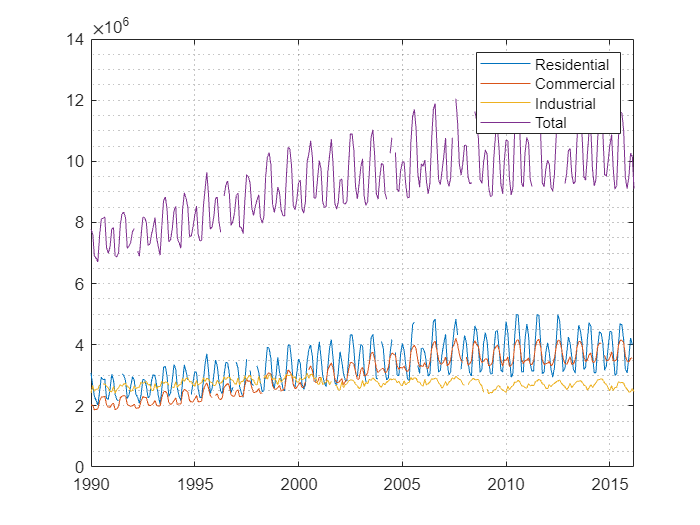

plot(dates, usage)  
grid minor
legend(sectors)

## Task 1

One of the most common ways to normalize data is to shift it so that it's mean is centered on zero (i.e. the data has zero mean) and scale the data so that it's standard deviation is one. This is called the *z*-score of the data. 

To normalize data using *z*-scores, you can use the `normalize` function.

`xNorm` `=` `normalize``(``x``)`

normTotal = normalize(total)

normTotal =    -1.2163
   -1.3382
   -1.9187
   -1.9753
   -2.0736
   -1.3805
   -0.9356
   -0.9219
   -0.8894
   -1.7028


## Task 2

By default, `normalize` acts on the columns of array `X`

normUsage = normalize(usage)

normUsage =    -0.3980   -1.5645   -2.2438   -1.2163
   -0.9918   -1.5392   -0.5241   -1.3382
   -1.4773   -1.7881   -1.8598   -1.9187
   -1.6856   -1.7691   -1.4102   -1.9753
   -1.8913   -1.7406   -1.4153   -2.0736
   -1.2726   -1.3537   -0.3465   -1.3805
   -0.6039   -1.1467       NaN   -0.9356
   -0.7127   -1.1381   -0.1890   -0.9219
   -0.6874   -1.1140   -0.1221   -0.8894
   -1.5832   -1.5349   -0.6730   -1.7028


## Task 3

If you don't want to change the scale of the data, you can just center the data on zero by including the argument `"center"` set to `"mean"`.

`xCenter` `=` `normalize``(``X``,``"center"``,``"mean")`

centeredUsage = normalize(usage, "center", "mean")

centeredUsage = 1.0e+06 *

   -0.2798   -1.0203   -0.3120   -1.4976
   -0.6972   -1.0038   -0.0729   -1.6477
   -1.0385   -1.1661   -0.2586   -2.3624
   -1.1849   -1.1537   -0.1961   -2.4321
   -1.3295   -1.1351   -0.1968   -2.5532
   -0.8946   -0.8828   -0.0482   -1.6997
   -0.4245   -0.7478       NaN   -1.1520
   -0.5010   -0.7422   -0.0263   -1.1351
   -0.4832   -0.7265   -0.0170   -1.0951
   -1.1129   -1.0010   -0.0936   -2.0966


## Task 4

How has the usage in each sector changed relative to the usage in 1990 when the first data point was recorded?

You can normalize data by the first value in each column by including the `"scale"` argument and setting it to `"first"`.

`xScale` `=` `normalize``(``X``,``"scale"``,``"first"``)`

scaledUsage = normalize(usage, "scale", "first")

scaledUsage =     1.0000    1.0000    1.0000    1.0000
    0.8644    1.0082    1.0986    0.9807
    0.7535    0.9277    1.0220    0.8887
    0.7060    0.9338    1.0478    0.8797
    0.6590    0.9431    1.0475    0.8641
    0.8003    1.0682    1.1088    0.9740
    0.9530    1.1352       NaN    1.0445
    0.9281    1.1379    1.1178    1.0467
    0.9339    1.1457    1.1216    1.0518
    0.7293    1.0096    1.0900    0.9229


## Task 5

You can also stretch or compress data so that it's maximum and minimum values are within a specified range 

[*a*,*b*].

`xRange` `=` `normalize``(``X``,``"range"``,``[``a` `b``])`

rangeUsage = normalize(usage, "range", [-1 1])

rangeUsage =    -0.2914   -0.8753   -0.9030   -0.6039
   -0.5732   -0.8612   -0.1963   -0.6602
   -0.8036   -1.0000   -0.7452   -0.9284
   -0.9024   -0.9894   -0.5604   -0.9546
   -1.0000   -0.9735   -0.5625   -1.0000
   -0.7064   -0.7577   -0.1233   -0.6797
   -0.3891   -0.6423       NaN   -0.4742
   -0.4408   -0.6375   -0.0585   -0.4678
   -0.4287   -0.6240   -0.0310   -0.4528
   -0.8538   -0.8588   -0.2575   -0.8286
